Test binocularity from L6 input

# Paper3: 1st test

How will a 4*8 binocular patch work?

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_Binocular/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/LARGE16/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_binocular_realLGN/']; % V1D2
DataFolder4 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

addpath(DataFolder4)
addpath(SaveToFolder)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPt = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPt))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Figures/Demo090324/']; % V1D2
close all

## 2. Test for different x for E and I; yE and yI kept as 1 -- All killed are folded back

first get basic function information

Too time comsuming. --->> using HPC

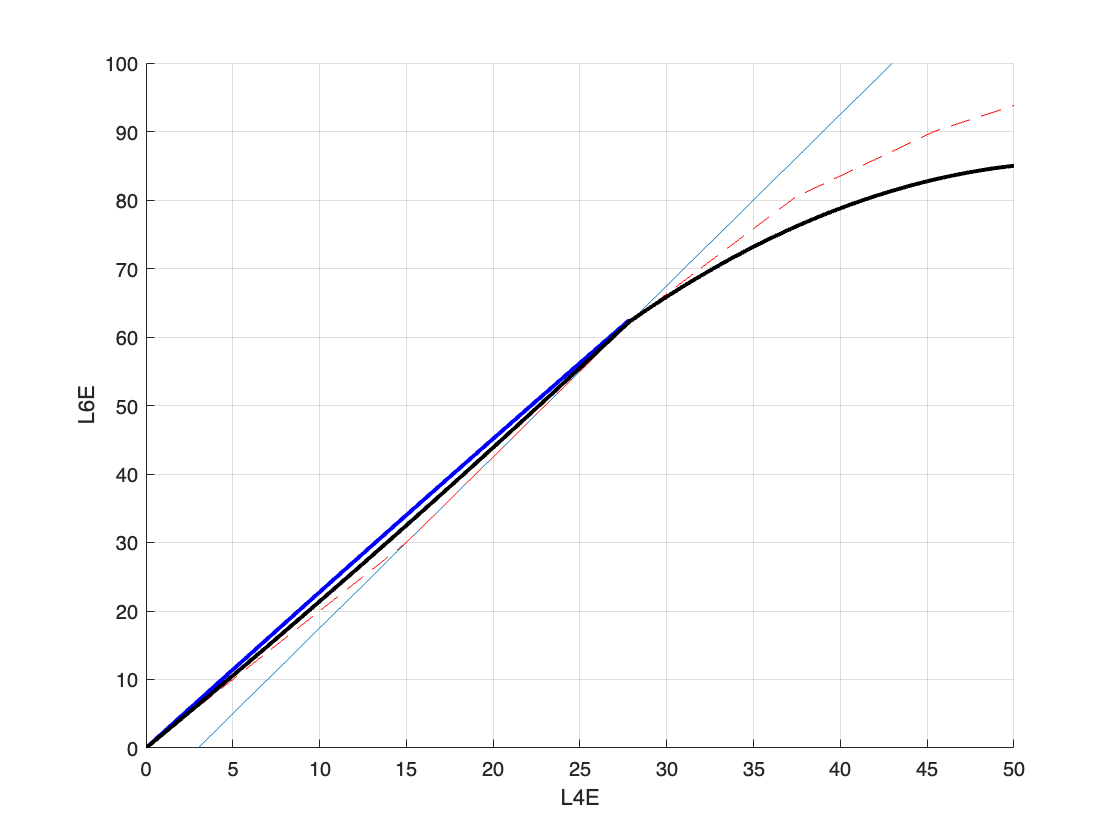

close all
ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];

L6pars = {};
%L6pars{2} = {2.5,3,[28; 31.5;37.4],[62.5; 69; 80.4],'quadratic'};
%L6pars{2} = {2.5,3,62.5,86,80.4,106,90};
L6pars{5} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 15 29],[0,32.5],[28 32 50],[69 85]}};

L6pars{4} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 15 29],[0,34],[28 32 50],[69 85]}};
L6pars{3} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 15 28],[1,34]}};
L6pars{2} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 10 15],[0,20],{[8 21.5 25],[0.04,0]}}}; % {[10 20 25],[0.04,0.02]}
L6pars{1} = {2.5,3,62.5,86,80.4,106,90,142.2, 102, 166.7, 108, 210, 118,{[0 10 15],[0,20]}};
%L6pars{1} = {2.5,3,[28; 40; 50],[62.5; 84; 96],'quadratic'};
xx = 0:0.1:50;
yy = L6Convert(xx, L6pars{1});
zz = L6Convert(xx, L6pars{2});
ww = L6Convert(xx, L6pars{4});
rr = L6Convert(xx, L6pars{5});
figure(99)
hold on
grid on
plot(xx,2.5*(xx-3))
plot(xx,yy,'r--')
%plot(xx,zz,'k-','LineWidth',2)
plot(xx,ww,'b-','LineWidth',2)
plot(xx,rr,'k-','LineWidth',2)

ylim([0 100])
xlabel('L4E');ylabel('L6E')

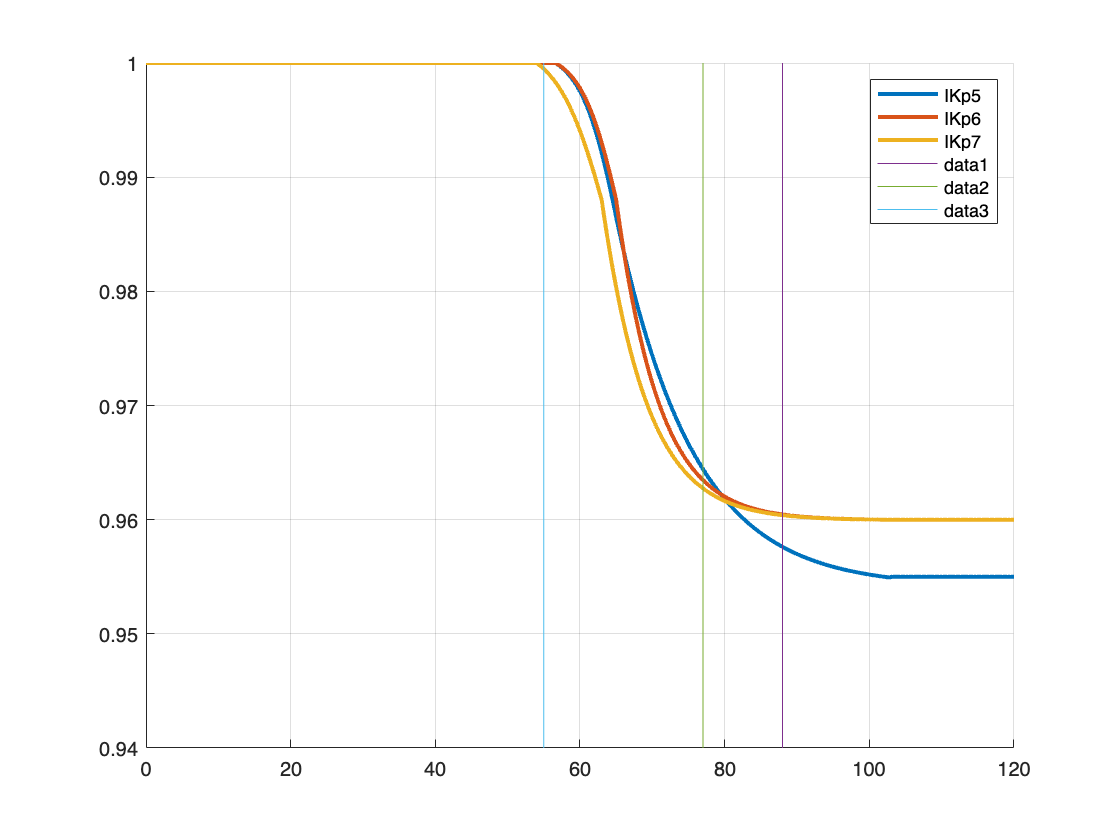


% Inhibition saturation info
IKp1.Thrsld1 = 56.6; IKp1.Thrsld2 = 68.6;
IKp1.Highist = 115;  IKp1.Slope = 0.95; % this is for new rule: multiplicative saturation
Isaturation = true;
IKp1.Mode = 'multisigmoid'; % or 'linear'
IKp1.IntaH = 5.5; IKp1.IntaL = -1;
IKp1.IntbL = 3; IKp1.IntbH = 0.5; % one side start from 3. another side start from 6

IKp2.Thrsld1 = 56.6; IKp2.Thrsld2 = 65;
IKp2.Highist = 103;  IKp2.Slope = 0.949; % this is for new rule: multiplicative saturation
IKp2.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp2.Mode = 'multisigmoid'; % or 'linear'
IKp2.IntaH = 4.5; IKp2.IntaL = -2.5;
IKp2.IntbL = 3.4; IKp2.IntbH = -0.3; % one side start from 3. another side start from 6

IKp3.Thrsld1 = 56.6; IKp3.Thrsld2 = 65;
IKp3.Highist = 103;  IKp3.Slope = 0.948; % this is for new rule: multiplicative saturation
IKp3.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp3.Mode = 'multisigmoid'; % or 'linear'
IKp3.IntaH = 3.8; IKp3.IntaL = -2.5;
IKp3.IntbL = 3.4; IKp3.IntbH = -0.3; % one side start from 3. another side start from 6

IKp4.Thrsld1 = 56.6; IKp4.Thrsld2 = 65;
IKp4.Highist = 103;  IKp4.Slope = 0.9525; % this is for new rule: multiplicative saturation
IKp4.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp4.Mode = 'multisigmoid'; % or 'linear'
IKp4.IntaH = 5; IKp4.IntaL = -2.5;
IKp4.IntbL = 3.4; IKp4.IntbH = -0.3; % one side start from 3. another side start from 6

IKp5.Thrsld1 = 56.6; IKp5.Thrsld2 = 65;
IKp5.Highist = 103;  IKp5.Slope = 0.955; % this is for new rule: multiplicative saturation
IKp5.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp5.Mode = 'multisigmoid'; % or 'linear'
IKp5.IntaH = 6.3; IKp5.IntaL = -2.5;
IKp5.IntbL = 3.4; IKp5.IntbH = -0.3; % one side start from 3. another side start from 6

IKp6.Thrsld1 = 56.6; IKp6.Thrsld2 = 65;
IKp6.Highist = 103;  IKp6.Slope = 0.96; % this is for new rule: multiplicative saturation
IKp6.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp6.Mode = 'multisigmoid'; % or 'linear'
IKp6.IntaH = 9.3; IKp6.IntaL = -2.5;
IKp6.IntbL = 3.4; IKp6.IntbH = -0.3; % one side start from 3. another side start from 6

IKp7.Thrsld1 = 54; IKp7.Thrsld2 = 63;
IKp7.Highist = 103;  IKp7.Slope = 0.96; % this is for new rule: multiplicative saturation
IKp7.down1 = 0.3; % how much does the first part goes down -- a number between 0 and 1
Isaturation = true;
IKp7.Mode = 'multisigmoid'; % or 'linear'
IKp7.IntaH = 9.3; IKp7.IntaL = -2.5;
IKp7.IntbL = 2.9; IKp7.IntbH = -0.3; % one side start from 3. another side start from 6

figure(100)
xx = 0:0.1:120;
IKpAll = {IKp1,IKp2,IKp3,IKp4,IKp5,IKp6,IKp7};
for IkpInd = 5:length(IKpAll)
[yy1,fac1] = InhMulp(xx,IKpAll{IkpInd});
hold on
plot(xx,fac1,'LineWidth',2,'DisplayName',sprintf('IKp%d',IkpInd))
end
%plot(60:100,1-(0:40)*0.05/40)
yyz = 0.94:0.01:1;
plot(88*ones(size(yyz)),yyz)
plot(77*ones(size(yyz)),yyz)
plot(55*ones(size(yyz)),yyz)
grid on
axis([0 120 0.94 1])
legend


L6parId = 5;
IkpInd = 7;
IKpUse = IKpAll{IkpInd};
EKpUse = {1,0,[50; 70; 100],[50; 60.5; 69],'quadratic'};

Load binocular results

close all
ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];
if strcmp(L6pars{L6parId}{end},'quadratic')
    L6Comment = sprintf('%s',L6pars{L6parId}{end})
elseif iscell(L6pars{L6parId}{end})
    L6Comment = sprintf('LowModi3');
    if length(L6pars{L6parId}{end}) == 4
        L6Comment = sprintf('LowHighQuadr5')
    end
    if iscell(L6pars{L6parId}{end}{end})
        L6Comment = sprintf('ContrTweak3');
    end
else
    L6Comment = sprintf('linear')
end

L6Comment = 'LowHighQuadr5'

IkpComment = sprintf('IKp%d',IkpInd);
loadStr = ['Bino' Comment L6Comment IkpComment];

% other parameters
lgnSF = 2.5;
lgnTF = 10;
Contr = 100%[19 42 66 100]

Contr = 100

switch Contr
    case 100
        ContrStr = '';
    otherwise
        ContrStr = sprintf('_Contr%d',Contr)
end
ParaEx = 1;
ParaEy = 1;
Conn_Reduc_TestS = 5; Conn_Reduc_TestC = 5;

loadStrUse = sprintf('%s_LGNSF%.1fTF%d%s-xE%.1fyE%.1f-Sd%.1fCd%.1f',...
                    loadStr,lgnSF,lgnTF,ContrStr, ParaEx, ParaEy,Conn_Reduc_TestS,Conn_Reduc_TestC);

load([SaveToFolder sprintf('NESSs-RLGNL6-EIdep_%s.mat',loadStrUse)],...
    'LDEOutAll')
LDEOutAllBino = LDEOutAll;

Test different combination of L6 for now

close all
lgnSF = 2.5;
for Contr = 100%[19 42 66 100]
    switch Contr
        case 100
            ContrStr = '';
        otherwise
            ContrStr = sprintf('_Contr%d',Contr)
    end

    for lgnTF = 10%[2 4 10 16 24] lgnTF is tested for 2 4 10 16 24

L6 binocular index: How much L6 portion is included?

        for L6BinoIndex = [0 .1 .2 .3 .4 .5 1]
            xEAll = 0:0.25:1
            MonocuFlag = true

            for xEInd = length(xEAll)   % 1:length(xEAll)             

                if strcmp(L6pars{L6parId}{end},'quadratic')
                    L6Comment = sprintf('%s',L6pars{L6parId}{end})
                elseif iscell(L6pars{L6parId}{end})
                    L6Comment = sprintf('LowModi3');
                    if length(L6pars{L6parId}{end}) == 4
                        L6Comment = sprintf('LowHighQuadr5')
                    end
                    if iscell(L6pars{L6parId}{end}{end})
                        L6Comment = sprintf('ContrTweak3');
                    end
                else
                    L6Comment = sprintf('linear')
                end
                IkpComment = sprintf('IKp%d',IkpInd);
                tic
                %AngleList = {'0.0'}; % only vertical for now
                AngleList = {'0.0','7.5','15.0','22.5'};
                DomList =  {'Small','Large'};%{'Small','Large','LARGER'};

## 3. Set up initial conditions

                N_HCOutX = 4; N_HCOutY = 8; PixNumOut = N_HCOutX*N_HCOutY*NPixX*NPixY;
                N_HCinX = 4; N_HCinY = 4;
                NPixX = 10; NPixY = 10;

Parameters of L4 kernels

                AngleTestAll = 0:7.5:180; % 0:7.5:22.5; % has to be multiples of 7.5
                TestNum = length(AngleTestAll); ICTestAll = cell(TestNum,1);
                TestExSeq = xEAll(xEInd)*ones(size(AngleTestAll)); TestEySeq = 1*ones(size(AngleTestAll));
                TestIxSeq = TestExSeq;                             TestIySeq = TestEySeq;
                fprintf('xE=%.1f, yE=1, lgnTF = %d, Contr = %d, L6BinoIndex = %.1f',xEAll(xEInd),lgnTF,Contr,L6BinoIndex)

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

                ICData = load(sprintf('LDETracesV4D2_NewSmear_ang0.0.mat'));
                load('LDETracesV4D2_NewSmear_ang0.0.mat')
                LDEICPart = ICData.LDEEquv;

                LDEICOut = HCRotXY(LDEICPart,0,N_HCinX,N_HCinY,N_HCOutX,N_HCOutY,NPixX,NPixY,0);
                for TestId = 1:TestNum
                    ICTestAll{TestId} = LDEICOut;
                end
                LDEOutAll = cell(size(ICTestAll));
                NANFlag = false(size(ICTestAll));
                %BGFlagAllTest = cell(size(ICTestAll));

load equiv

                %PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
                %LDEEquv = PlotUse.LDEEquv;
                %LDEEquv = HCRot(LDEEquv,RotInd,N_HCOut,NPixX,NPixY,MirInd);

Hyperparameters of iterations

                p = 0.50;% 1-p for the original input
                EpocTest = 50;
                ExportFlag = 'xn';

                L2Diff_OneStepAll = zeros(length(ICTestAll),EpocTest+1);
                DiffVecAll = zeros(length(ICTestAll),EpocTest+1,3*NPixY*NPixX);

Since we are doing different network architectures now - need to separate inputs to the S C I functions!!!

                % Determine L4 Input from a range
                L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
                L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
                L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
                L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
                L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
                L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
                for PInd = 1:N_HC*NPixX*N_HC*NPixY
                    L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec);
                    L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec ;
                    L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec);
                    L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec ;
                    L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec);
                    L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec ;
                end
                L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
                L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
                L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);

## Compute NESSs for each angle

                for TestId = 1:TestNum
                    AngleInpt = AngleTestAll(TestId);

                    RotInd = floor(AngleInpt/45); % 0-3
                    MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
                    switch MirInd % find the corresponding source
                        case 0
                            AngSource = mod(AngleInpt,45);
                        case 1
                            AngSource = mod(-AngleInpt,45);
                    end

                    % Use the source, decide which response function for angle should I use
                    AngFuncCtgrCdid = 0:7.5:22.5;
                    [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));

                    AngPrint = AngleList{AngFuncCtgr};
                    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

load all precomputed domains

                    L4EmeshXAll = cell(size(DomList));
                    L4ImeshYAll = cell(size(DomList));
                    LDEFrfuncAll = cell(size(DomList));
                    for DomInd = 1:length(DomList)
                        FuncTemp = load(sprintf('Func200%s-%s-Ang%s-SF%.1fTF%d%s-%s.mat',...
                            DataPt,Comment,AngPrint,lgnSF,lgnTF,ContrStr,DomList{DomInd}),...
                            'LDEFrfunc','L4EmeshX','L4ImeshY');
                        L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
                        L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
                        LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
                    end

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

                    %    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
                    LGNlist = 5; L6list = 40;
                    OD_SMapModi = OD_SMap;

Needs to replace the midel row as "5" -- Background

                    %OD_SMapModi = OD_SMap(1:2*n_S_HC,1:2*n_S_HC);
                    if MonocuFlag
                        OD_SMapModi(n_S_HC+1:2*n_S_HC,1:end) = 5;
                        SaveStr = ['Mono' Comment L6Comment IkpComment];
                    else
                        SaveStr = ['Bino' Comment L6Comment IkpComment];
                    end

L6 kernel

                    L6ConvSig = 0.75;
                    L6ConvTruc = 1.5/(L6ConvSig);
                    Kersize = floor(2*L6ConvSig*L6ConvTruc);
                    if Kersize<=0
                        Kersize= 2; % at least 1
                    end
                    [x,y] = meshgrid(1:Kersize,1:Kersize);
                    c = Kersize/2;
                    exponent = ((x-c).^2+(y-c).^2)/(2*L6ConvSig^2);
                    L6Kernel = exp(-exponent);
                    L6Kernel(L6Kernel<exp(-(L6ConvTruc*1.0)^2/2))=0; % truncate
                    L6Kernel = L6Kernel + ...
                        L6Kernel(end:-1:1,:) + ...
                        L6Kernel(:,end:-1:1) + ...
                        L6Kernel(end:-1:1,end:-1:1);%symmetrize
                    L6Kernel = L6Kernel/sum(L6Kernel,'all'); % normalize
                    L6Kernel = L6Kernel/((sum(L6Kernel,'all') - L6Kernel(2,2))/(1-0.3));
                    L6Kernel(2,2) = 0.3;

LGN and L6 are blurred 

                    N_HCs = 3; % shrink to 2*2
                    FigOn = false;
                    LGNsmear = n_S_HC*0.2;
                    TruncLGN = 1;
                    LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMapModi,...
                        N_HCs,n_S_HC,LGNsmear,TruncLGN,FigOn);

                    if ~MonocuFlag
                        LGNFilt_Grating = [LGNFilt_Grating,zeros(size(LGNFilt_Grating,1),1)];
                    end

                    PixLGNCtgr = LGNIndSpat_Rec(...
                        LGNFilt_Grating,1:LGNlist,NnSPixel,N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,true);

                    % symmetrize !! This is actually trick, so I do it ad hoc
                    PixLGNCtgr = Ocu_LGNL6symm(PixLGNCtgr,N_HCOutX,N_HCOutY,NPixX,NPixY);

completely BG or not?

                    BGFlag = false;
                    if BGFlag
                        PixL6Ctgr(:,end) = 1; PixL6Ctgr(:,1:end-1) = 0;
                        PixLGNCtgr(:,end) = 1; PixLGNCtgr(:,1:end-1) = 0;
                    end

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

**Instead of rotating existing ctgr fields, I should simply permute 1234  **

                    MirInd = logical(MirInd);
                    CtgrOrder = [2,1;3,4]; % for lower left HC
                    CtgrOrderUse = rot90(CtgrOrder,RotInd);
                    if MirInd
                        %flipDim = mod(RotInd,2)+1; %1 for col 2 ofr row
                        CtgrOrderUse = flip(CtgrOrderUse,1);
                    end
                    CtgrOrderReadout = ...
                        [CtgrOrderUse(1,2);
                        CtgrOrderUse(1,1);
                        CtgrOrderUse(2,1);
                        CtgrOrderUse(2,2)];
                    %    for Ctgr = 1:4
                    %         PixL6Ctgr(:,Ctgr) = ...
                    %             HCRot_Rec(PixL6Ctgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
                    %         PixLGNCtgr(:,Ctgr) = ...
                    %             HCRot_Rec(PixLGNCtgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
                    %    end

                    % let's implement something cheap now for 45 deg
                    PixLGNCtgr = PixLGNCtgr(:,[CtgrOrderReadout',5]);

Get pixelwise connectivities

NOTE: NEED to modify AveSpatKer_Rec to implement the ocular modulation of connectivity kernels    

                    ParaEx = TestExSeq(TestId); ParaEy = TestEySeq(TestId);
                    ParaIx = TestIxSeq(TestId); ParaIy = TestIySeq(TestId);

                    C_SS_mean = sparse(AveSpatKer_Rec(C_SS_Pixel_Us,N_HC,...
                        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                    C_CS_mean = sparse(AveSpatKer_Rec(C_CS_Pixel_Us,N_HC,...
                        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                    C_IS_mean = sparse(AveSpatKer_Rec(C_IS_Pixel_Us,N_HC,...
                        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                    C_SC_mean = sparse(AveSpatKer_Rec(C_SC_Pixel_Us,N_HC,...
                        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                    C_CC_mean = sparse(AveSpatKer_Rec(C_CC_Pixel_Us,N_HC,...
                        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                    C_IC_mean = sparse(AveSpatKer_Rec(C_IC_Pixel_Us,N_HC,...
                        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
                    C_SI_mean = sparse(AveSpatKer_Rec(C_SI_Pixel_Us,N_HC,...
                        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
                    C_CI_mean = sparse(AveSpatKer_Rec(C_CI_Pixel_Us,N_HC,...
                        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
                    C_II_mean = sparse(AveSpatKer_Rec(C_II_Pixel_Us,N_HC,...
                        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));

                    Conn_Reduc_TestS = 5; Conn_Reduc_TestC = 5;
                    Reduc_S = Conn_Reduc_TestS*(1-CplxR); Reduc_C = Conn_Reduc_TestC*CplxR;
                    P_SS_rate = (N_SS-Reduc_S)/N_SS; C_SS_meanU = C_SS_mean * P_SS_rate;
                    P_SC_rate = (N_SC-Reduc_C)/N_SC; C_SC_meanU = C_SC_mean * P_SC_rate;
                    P_CS_rate = (N_CS-Reduc_S)/N_CS; C_CS_meanU = C_CS_mean * P_CS_rate;
                    P_CC_rate = (N_CC-Reduc_C)/N_CC; C_CC_meanU = C_CC_mean * P_CC_rate;

Firing rate suppresion

                    %     EKp.Thrsld = 50; EKp.Highist = [200,150]; EKp.HardBound = 200; EKp.Slope = 0;
                    %
                    %     IKp.Thrsld = 70; IKp.Highist = [100,95];  IKp.HardBound = 120; IKp.Slope = 1; % 1; 0.9(95); 0.8(9)

set up IC

                    tic
                    ICUse = ICTestAll{TestId}; %
                    IniTest = ICUse;
                    %IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
                    %IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
                    %IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);


start iteration

                    [LDEOutAll{TestId},LDEIL2Diff{TestId},L2DiffNormNeib{TestId},~,~,FuncUse,...
                        NANFlag(TestId)] = ...
                        LDEIteration_135FuncMain_CombDom_RealLGNL6_L6BinoIndex(...
                        PixLGNCtgr,L6Kernel,IniTest,p,L6pars{L6parId}, EpocTest,...
                        C_SS_meanU,C_CS_meanU,C_IS_mean,...
                        C_SC_meanU,C_CC_meanU,C_IC_mean,...
                        C_SI_mean, C_CI_mean, C_II_mean,...
                        L4SEp, L4SIp, ...
                        L4CEp, L4CIp, ...
                        L4IEp, L4IIp, ...
                        L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
                        L6BinoIndex, LDEOutAllBino{TestId}{end}, ...
                        N_HCOutY,NPixX,NPixY,Isaturation,'xn',EKpUse,IKpUse)  ;
                    LDEEquv = LDEOutAll{TestId}{end};

                    RunTime = toc;
                    sprintf('RunTime = %.2f',RunTime)

                    if ~NANFlag(TestId)
                        for EpcInd = 1:EpocTest+1
                            LDEPertRslt = LDEOutAll{TestId}{EpcInd};
                            SDiff = LDEPertRslt.S - LDEEquv.S;
                            SDiffHC = reshape(SDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
                            SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
                            CDiff = LDEPertRslt.C - LDEEquv.C;
                            CDiffHC = reshape(CDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
                            CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
                            IDiff = LDEPertRslt.I - LDEEquv.I;
                            IDiffHC = reshape(IDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
                            IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);

                            L2Diff_OneStepAll(TestId,EpcInd) = ...
                                sqrt(sum((SDiff*(1-CplxR)+CDiff*CplxR).^2,'all'));%sqrt(sum([SDiff;CDiff;IDiff].^2));
                            DiffVecAll(TestId,EpcInd,:) = [SDiff;CDiff;IDiff];
                        end
                    end
                end

   Comment below if don't need to save data (usually for setting up new NESSs) 

                SaveStrUse = sprintf('%s_LGNSF%.1fTF%d%s-L6BinoInd%.1f-xE%.1fyE%.1f-Sd%.1fCd%.1f',...
                    SaveStr,lgnSF,lgnTF,ContrStr, L6BinoIndex, ParaEx, ParaEy,Conn_Reduc_TestS,Conn_Reduc_TestC);

                save([SaveToFolder sprintf('NESSs-RLGNL6-EIdep-L6BinoTest_%s.mat',SaveStrUse)],...
                    'LDEOutAll','LDEIL2Diff','L2DiffNormNeib','L2Diff_OneStepAll','DiffVecAll',...
                    'TestExSeq','TestEySeq','AngleTestAll','L6pars')
                RunTime = toc;
                fprintf('RunTime = %.2f',RunTime)


            end
        end % L6BinoIndex
    end
end

xEAll =          0    0.2500    0.5000    0.7500    1.0000


MonocuFlag = logical
   1


L6Comment = 'LowHighQuadr5'

xE=1.0, yE=1, lgnTF = 10, Contr = 100, L6BinoIndex = 0.0

Brace indexing is not supported for variables
of this type.